syms rho Pi
syms k l_0 l epsilon % Universal muscle parameters
syms g_0 g_0_b g_0_t % Poses
syms k_b l_0_b l_b epsilon_b % Bottom muscle parameters
syms k_t l_0_t l_t epsilon_t % Top muscle parameters

assume([rho k l_0 l epsilon k_b l_0_b l_b epsilon_b k_t l_0_t l_t epsilon_t], "real")

syms k_epsilon k_k
assume([k_epsilon k_k], "real")

% Parameter initialization
g_0_b = SE2(0, 0, pi/2);
g_0_t = SE2(-rho, 0, pi/2);

struct_vals = struct();
struct_vals.Pi = pi;

struct_vals.rho = 0.03; % meters
struct_vals.k_k = 0.1; % Newtons/meter
struct_vals.k_epsilon = 1000000000; % Newtons/meter
struct_vals.l_0_t = 0.1; % meters
struct_vals.l_0_b = 0.08; % meters

struct_syms_top = struct();
struct_syms_top.k = k_t;
struct_syms_top.l_0 = l_0_t;
struct_syms_top.l = l_t;
struct_syms_top.epsilon = epsilon_t;

struct_syms_bot = struct();
struct_syms_bot.k = k_b;
struct_syms_bot.l_0 = l_0_b;
struct_syms_bot.l = l_b;
struct_syms_bot.epsilon = epsilon_b;

% Construct endpoint positional constraint
g_end_t = sym(g_0_t) * expm_se2(l_t, 0, l_t*k_t);
g_end_t = subs(g_end_t, l_t, l_0_t + epsilon_t);

g_end_b = sym(g_0_b) * expm_se2(l_b, 0, l_b*k_b);
g_end_b = subs(g_end_b, l_b, l_0_b + epsilon_b);

delta_g = (g_end_t*[0;0;1] - g_end_b*[0;0;1]);
constraint_posn = dot(delta_g, delta_g) - rho^2 == 0;
constraint_posn

$$constraint\_posn = {\left(\rho +\frac{\cos\left(k_{b}\,\left(\epsilon_{b}+l_{0,b}\right)\right)-1}{k_{b}}-\frac{\cos\left(k_{t}\,\left(\epsilon_{t}+l_{0,t}\right)\right)-1}{k_{t}}\right)}^{2}-\rho^{2}+{\left(\frac{\sin\left(k_{b}\,\left(\epsilon_{b}+l_{0,b}\right)\right)}{k_{b}}-\frac{\sin\left(k_{t}\,\left(\epsilon_{t}+l_{0,t}\right)\right)}{k_{t}}\right)}^{2}=0$$

% Construct orientation constraint equation
l = l_0 + epsilon;
l_b = subs(l, struct_syms_bot);
l_t = subs(l, struct_syms_top);
constraint_orntn = k_b*l_b - k_t*l_t == 0;
constraint_orntn

$$constraint\_orntn = k_{b}\,\left(\epsilon_{b}+l_{0,b}\right)-k_{t}\,\left(\epsilon_{t}+l_{0,t}\right)=0$$

% Construct objective function
U = k_epsilon * epsilon^2 + k_k * k^2;
U_all = subs(U, struct_syms_top) + subs(U, struct_syms_bot)

$$U\_all = k_{\epsilon }\,{\epsilon_{b}}^{2}+k_{\epsilon }\,{\epsilon_{t}}^{2}+k_{k}\,{k_{b}}^{2}+k_{k}\,{k_{t}}^{2}$$

## Optimization

q = [epsilon_b, k_b, epsilon_t, k_t];
g_bt = g_0_b^-1 * g_0_t;

constraint_LA = g_bt*se2(l_t, 0, k_t*l_t) - se2(l_b, 0, k_b*l_b)*g_bt

$$constraint\_LA = \left(\begin{array}{ccc} 0 & k_{b}\,\left(\epsilon_{b}+l_{0,b}\right)-k_{t}\,\left(\epsilon_{t}+l_{0,t}\right) & \epsilon_{t}-\epsilon_{b}-l_{0,b}+l_{0,t}+k_{b}\,\rho \,\left(\epsilon_{b}+l_{0,b}\right)\\ k_{t}\,\left(\epsilon_{t}+l_{0,t}\right)-k_{b}\,\left(\epsilon_{b}+l_{0,b}\right) & 0 & 0\\ 0 & 0 & 0 \end{array}\right)$$

v_constraints_LA = [constraint_LA(1, 2); constraint_LA(1, 3); constraint_LA(2, 3)]

$$v\_constraints\_LA = \left(\begin{array}{c} k_{b}\,\left(\epsilon_{b}+l_{0,b}\right)-k_{t}\,\left(\epsilon_{t}+l_{0,t}\right)\\ \epsilon_{t}-\epsilon_{b}-l_{0,b}+l_{0,t}+k_{b}\,\rho \,\left(\epsilon_{b}+l_{0,b}\right)\\ 0 \end{array}\right)$$

% Solve for any geometrically-valid configuration

test_struct_vals = struct_vals;
test_struct_vals.epsilon_b = 0;
test_struct_vals.k_b =0;
range = [-test_struct_vals.l_0_b * 0.8, test_struct_vals.l_0_b * 0.8;
         -test_struct_vals.l_0_b * 0.8, test_struct_vals.l_0_t * 0.8;
         -inf, inf];
soln = vpasolve(subs(v_constraints_LA, test_struct_vals), [k_b, epsilon_t, k_t], range);

soln.k_b = test_struct_vals.k_b;
soln.epsilon_b = test_struct_vals.epsilon_b;

print_results(soln, u=U_all, struct_vals=struct_vals)

Bottom strain:
     0

Bottom curvature:
     0

Top strain:


$$-0.02$$

Top curvature:


$$0$$

Energy:
       40000



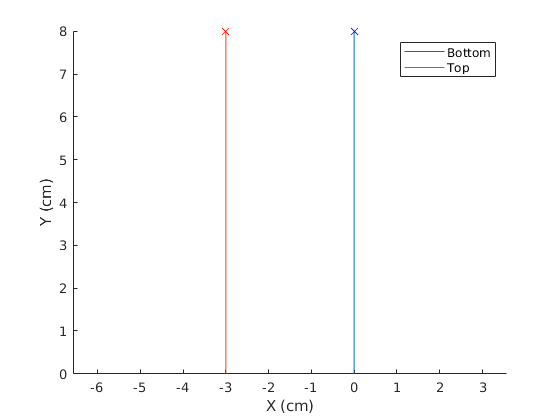

plot_results(soln, struct_vals)

struct_vals.l_0_b = 0.075;
struct_vals.l_0_t = 0.14;
struct_vals.k_k = 0.001; % Newton meters
struct_vals.k_epsilon = 1000;
f_generate_func = @(sym_func) matlabFunction(subs(sym_func, struct_vals));

f_U = f_generate_func(U_all);
f_constraint = f_generate_func(v_constraints_LA(1:2));

% x: epsilon_b, epsilon_t, k_b, k_t
f_obj = @(x) f_U(x(1), x(2), x(3), x(4));
f_nonlcon = @(x) smart_deal([], f_constraint(x(1), x(2), x(3), x(4)));
x_0 = [0, 0, 0, 0];

opt_fmincon = optimoptions('fmincon', "algorithm", "interior-point");

v_soln = fmincon(f_obj, x_0, [], [], [], [], [], [], f_nonlcon, opt_fmincon);


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


struct_soln = struct();
struct_soln.epsilon_b = v_soln(1);
struct_soln.epsilon_t = v_soln(2);
struct_soln.k_b = v_soln(3);
struct_soln.k_t = v_soln(4);

print_results(struct_soln)

Bottom strain:
    0.0125

Bottom curvature:
  -16.8434

Top strain:
   -0.0083

Top curvature:
  -11.1894



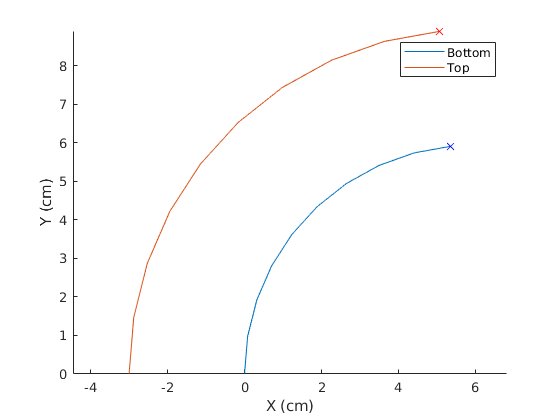

plot_results(struct_soln, struct_vals, g_0_b=g_0_b, g_0_t=g_0_t)

mat_k = diag([k_epsilon, 100000000, k_k]);
ad_b_inv = ad_se2(0, rho/2, 0);
ad_t_inv = ad_se2(0, -rho/2, 0);
sigma = (1/l_0_t^2)*ad_t_inv'*mat_k*ad_t_inv + (1/l_0_b^2)*ad_b_inv'*mat_k*ad_b_inv ;

tild_h_o = inv(sigma' * sigma) * sigma' * (ad_t_inv / l_0_t + ad_b_inv / l_0_b) * mat_k * [0; 0; 1]

val_tild_h_o = eval(subs(tild_h_o, struct_vals))

val_tild_h_o = 	1.0e+-3 *

   -0.0047
         0
    0.5702


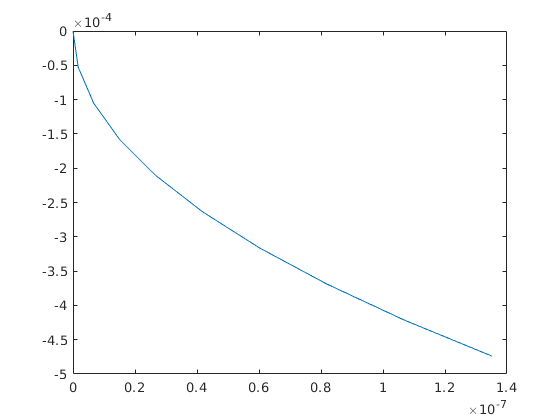

t = linspace(0, 1, 10);
g_out = zeros(3, length(t));
g_0_val = SE2(0, 0, pi/2);
for i = 1 : length(t)
    SE2_pose_i = g_0_val * expm_se2(val_tild_h_o(1)*t(i), 0, val_tild_h_o(3)*t(i));
    g_out(:, i) = [SE2_pose_i(1, 3); SE2_pose_i(2, 3); atan2(SE2_pose_i(2, 1), SE2_pose_i(1, 1))];
end
g_out = g_out*100; % Convert to centimeters

figure();
plot(g_out(1, :), g_out(2, :))

function g_out = calc_posn(g_0, l_0, epsilon, k, options)
% Calculate (and interpolate) positions given an initial pose, a default length,
% and a curvature.
% - g_0: Initial pose (SE2 matrix)
% - l_0: Neutral (unstrained) length
% - epsilon: Strain
% - options: use options.t to determine the timestamp. Defaults to 1.
    arguments
        g_0
        l_0
        epsilon
        k
        options.t (1, :) double = 1;
    end

    l = l_0 + epsilon;
    
    g_out = zeros(3, length(options.t));
    
    for i = 1 : length(options.t)
        SE2_pose_i = g_0 * expm_se2(l*options.t(i), 0, l*k*options.t(i));
        g_out(:, i) = [SE2_pose_i(1, 3); SE2_pose_i(2, 3); atan2(SE2_pose_i(2, 1), SE2_pose_i(1, 1))];
    end
end

function print_results(soln, options)
    arguments
        soln
        options.U = nan;
        options.struct_vals = nan;
    end
    for i = 1
        disp("Bottom strain:");
        disp(soln.epsilon_b)
        
        disp("Bottom curvature:");
        disp(soln.k_b)
        
        disp("Top strain:");
        disp(soln.epsilon_t)
        
        disp("Top curvature:");
        disp(soln.k_t)
    end
    
    if ~isnan(options.U) && isfield(options.struct_vals, "k_k")
        disp("Energy:")
        disp(eval(subs(subs(options.U, options.struct_vals), soln)));
    end
end

function plot_results(soln, struct_vals, options)
    arguments
        soln
        struct_vals
        options.g_0_b = SE2(0, 0, pi/2);
        options.g_0_t = SE2(-struct_vals.rho, 0, pi/2);
    end
    options.g_0_b = subs(options.g_0_b, struct_vals);
    options.g_0_t = subs(options.g_0_t, struct_vals);
    
    n = 10;
    g_bot = calc_posn(options.g_0_b, struct_vals.l_0_b, soln.epsilon_b, soln.k_b, t=linspace(0, 1, n));
    g_top = calc_posn(options.g_0_t, struct_vals.l_0_t, soln.epsilon_t, soln.k_t, t=linspace(0, 1, n));
    
    g_bot = g_bot * 100;
    g_top = g_top * 100;
    
    figure()
    hold on;
    plot(g_bot(1, :), g_bot(2, :))
    plot(g_top(1, :), g_top(2, :))
    plot(g_top(1, end), g_top(2, end), 'rx');
    plot(g_bot(1, end), g_bot(2, end), 'bx');
    
    legend("Bottom", "Top")
    xlabel("X (cm)")
    ylabel("Y (cm)")
    axis equal
end